df_raw = readtable('Vin');
t = table2array(df_raw(20480:364544+20479,1));
Vin = table2array(df_raw(20480:364544+20479,2));


plot(t,Vin, 'LineWidth', 1.5)
hold on

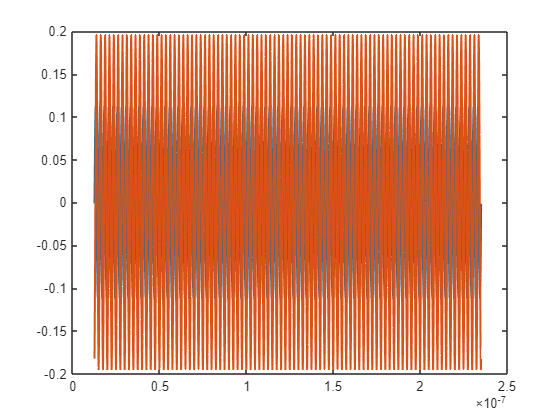

df_raw = readtable('Vout');
t = table2array(df_raw(20480:364544+20479,1));
Vout = table2array(df_raw(20480:364544+20479,2));

plot(t,Vout, 'LineWidth', 1.5)
hold off

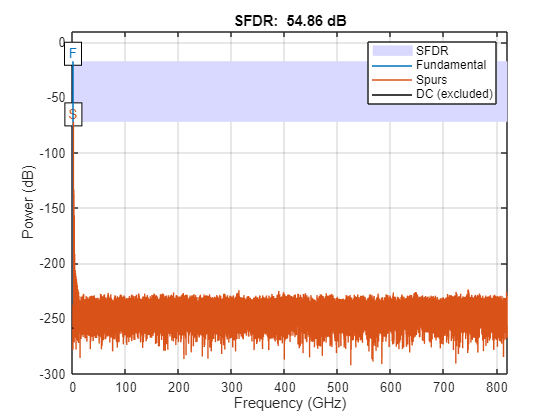



fs = 1.6384e12;     % Frecuencia de muestreo (Hz) 
sfdr(Vout,fs) ;


ENOB = (sfdr(Vout,fs)-1.76)/6.02

ENOB = 8.8208

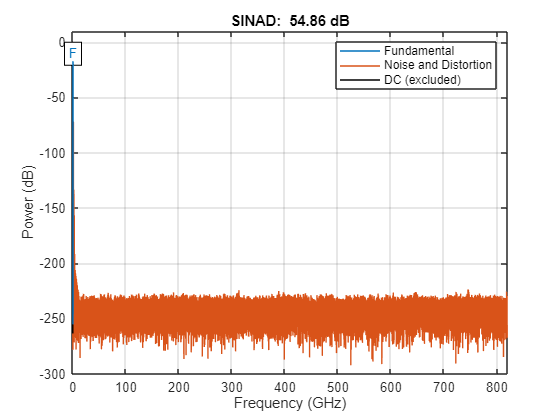


sinad(Vout, fs);

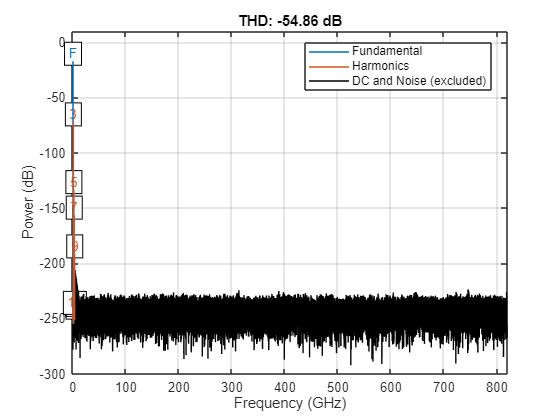

thd(Vout,fs,10,"aliased");

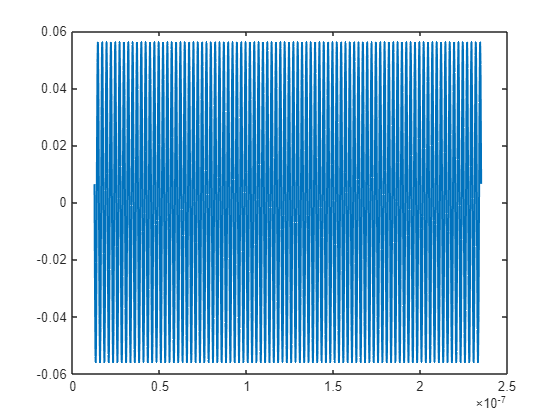

df_raw = readtable('Vo');
t = table2array(df_raw(20480:364544+20479,1));
Vo = table2array(df_raw(20480:364544+20479,2));


plot(t,Vo, 'LineWidth', 1.5)

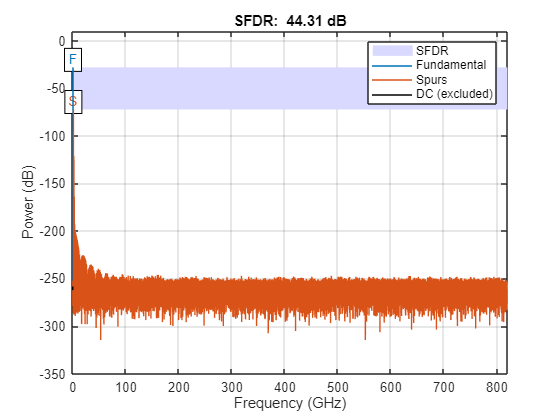


sfdr(Vo,fs,1) ;

xx = sfdr(Vo,fs);
thd(Vout,fs,10,"aliased");

hold off

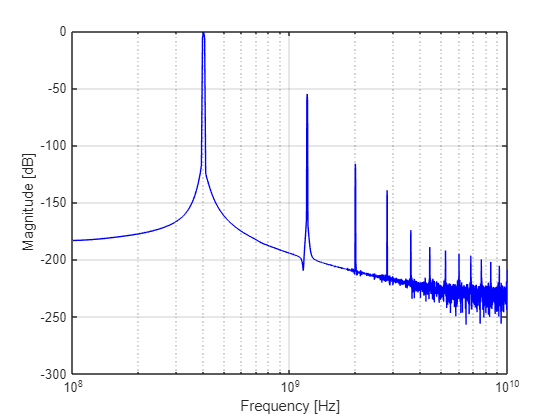

% fs = 409.6e9;     % Frecuencia de muestreo (Hz) 
N = length(Vout);
x_win = Vout .* hann(N);          % Aplicar ventana para reducir leakage
X = fft(x_win,N);
X_mag = abs(X(1:N/2));          % Magnitud de la mitad positiva
X_db = 20*log10(X_mag / max(X_mag)); % Normalización a 0 dB
f = (0:N/2-1)*(fs/N);           % Eje de frecuencia

% base = 4*1024;
% NFFT = base * ceil(length(Vout)/base);
% FFT_OUT = fftshift(abs(fft(Vout,NFFT))/length(Vout));
%  fft_abs = abs(FFT_OUT)
% fft_db = 20*log10(fft_abs/max(fft_abs));
% f_v = fs*(-NFFT/2:NFFT/2-1)/NFFT;

% figure;
% semilogx(f_v,fft_db, 'b');
% grid on;
% xlim([1e8,1e10]);

% l = length(Vout);
% y = fft(Vout);
% p2 = abs(y/l);
% p1 = p2(1:floor(l/2)+1);
% p1(2:end-1) = 2*p1(2:end-1);
% f_vec = (fs*(0:floor(l/2))/l);
% 
% 
% figure;
% semilogx(f_vec,20*log10(p1));
% grid on;
% xlim([1e8,1e10]);
% snr_db = 30;
% signal_power = mean(abs(Vout.^2));
% snr_lineal = 10^(snr_db/10);
% noise_pow = signal_power / snr_lineal;
% noise = sqrt(noise_pow) * randn(size(Vout));
% 
% vpot_noise = Vout+noise;

% NFFT_PLOT = 4*1024*97;
% vec_frec = (0:NFFT_PLOT-1)* fs / NFFT_PLOT; 
% 
% 20*log10(fft_abs/max(fft_abs))
% H_vout = 20*log10(abs(fft(Vout, NFFT_PLOT))/max(abs(fft(Vout, NFFT_PLOT))));
% 
% pos = 1:(floor(NFFT_PLOT/2)+1);
% vec_frec_pos = vec_frec(pos);
% H_vout_db = H_vout(pos);
% 
% figure;
% semilogx(vec_frec_pos, H_vout_db);
% xlim([1e7,1e10]);
% grid on;


% Graficar
figure;
plot(f, X_db, 'b'); grid on;
xlabel('Frequency [Hz]');
ylabel('Magnitude [dB]');
% ylim([-200 10]);
xlim([1e8,1e10]);
set(gca, 'XScale', 'log');

% % Calcular parámetros para FFT
% dt = t(2) - t(1);        % Paso temporal
% Fs = 1/dt;               % Frecuencia de muestreo
% N = length(Vout);        % Número de muestras
% 
% % Aplicar ventana de Hann para reducir el leakage
% window = hann(N);
% Vout_windowed = Vout .* window;
% 
% % Calcular FFT
% Y = fft(Vout_windowed);
% Y = Y(1:N/2);                      % Mantener solo mitad positiva
% f = (0:N/2-1)*(Fs/N);              % Vector de frecuencias
% magnitude = abs(Y)/(sum(window)/2);  % Magnitud normalizada
% 
% % Graficar espectro de frecuencia
% figure;
% semilogx(f, magnitude, 'LineWidth', 1.5)
% xlabel('Frecuencia (Hz)')
% ylabel('Magnitud')
% title('Espectro de Frecuencia de V_{out}')
% grid on;

% figure;
% % Parámetros de la señal
% Fs = 409.6e9;     % Frecuencia de muestreo (Hz) 
% T = 1/Fs;             % Periodo de muestreo
% L = 1024*17;             % Número de muestras
% 
% % Aplicar la FFT
% Y = fft(Vout);
% 
% % Calcular el espectro de amplitud
% P2 = 20*log10(abs(Y/L));         % Espectro bilateral
% P1 = P2(1:L/2+1);      % Espectro unilateral
% P1(2:end-1) = 2*P1(2:end-1); % Corregir amplitud
% % 
% % % Eje de frecuencias
% f = Fs*(0:(L/2))/L;
% % 
% % % Graficar
% semilogx(f, P1)
% % title('Espectro de Amplitud')
% % xlabel('Frecuencia (Hz)')
% % ylabel('|P1(f)|')
% % grid on